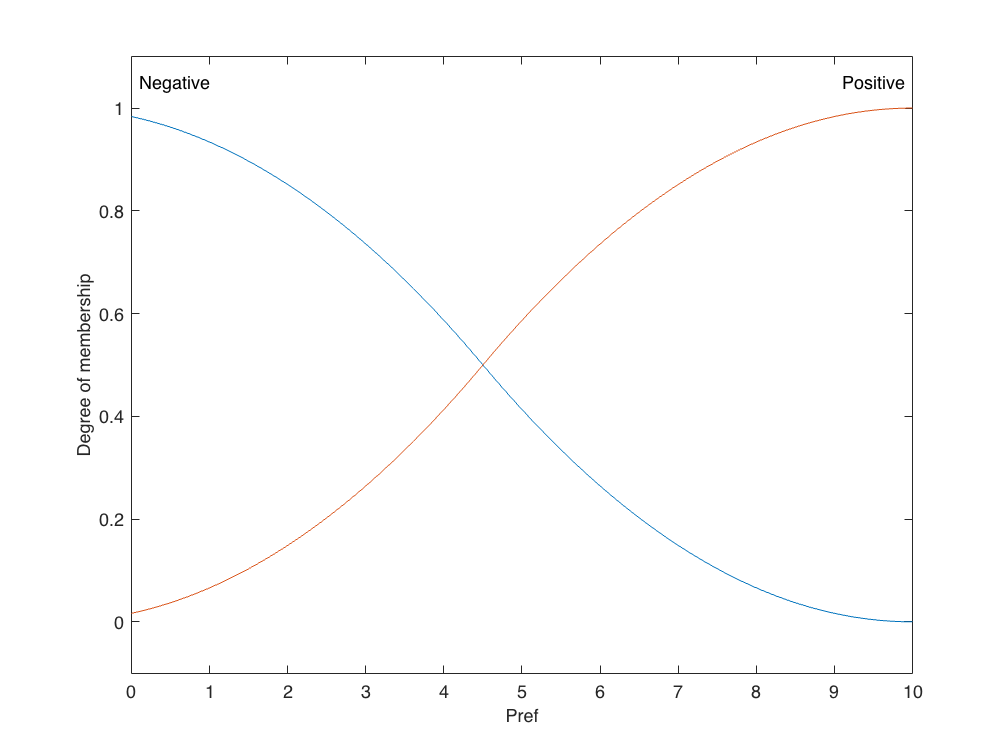

%Neurofeedback Fuzzy inference system
%% Version V1
% Authors - Mario De Los Santos, Felipe Orihuela-Espina, Javier Herrara-Vega
% Date - February 9th, 2022
% Email - madlsh3517@gmail.com

cpFIS = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFs', 6, ...
    'AddRule', 'none');
%Inputs

cpFIS.Inputs(1).Name = 'Pref';
%cpFIS.Inputs(1).Range = [-5, 20]; 
cpFIS.Inputs(1).Range = [0, 10]; 
cpFIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cpFIS.Inputs(1).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
%cpFIS.Inputs(1).MembershipFunctions(1).Parameters = [0 20];
cpFIS.Inputs(1).MembershipFunctions(1).Parameters = [-1 10];
cpFIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cpFIS.Inputs(1).MembershipFunctions(2).Type ='smf'; %S-shaped memebersh
cpFIS.Inputs(1).MembershipFunctions(2).Parameters = [-1 10];
%cpFIS.Inputs(1).MembershipFunctions(2).Parameters = [0 20];

% cpFIS.Inputs(2).Name = 'Pobs';
% cpFIS.Inputs(2).Range = [3, 10]; 
% cpFIS.Inputs(2).MembershipFunctions(3).Name = 'Negative';
% cpFIS.Inputs(2).MembershipFunctions(3).Type ='zmf'; %Z-shaped memebership function
% cpFIS.Inputs(2).MembershipFunctions(3).Parameters = [3 10];
% cpFIS.Inputs(2).MembershipFunctions(4).Name = 'Positive';
% cpFIS.Inputs(2).MembershipFunctions(4).Type ='smf'; %S-shaped memebersh
% cpFIS.Inputs(2).MembershipFunctions(4).Parameters = [3 10];

plotmf(cpFIS, 'input', 1, 1000);

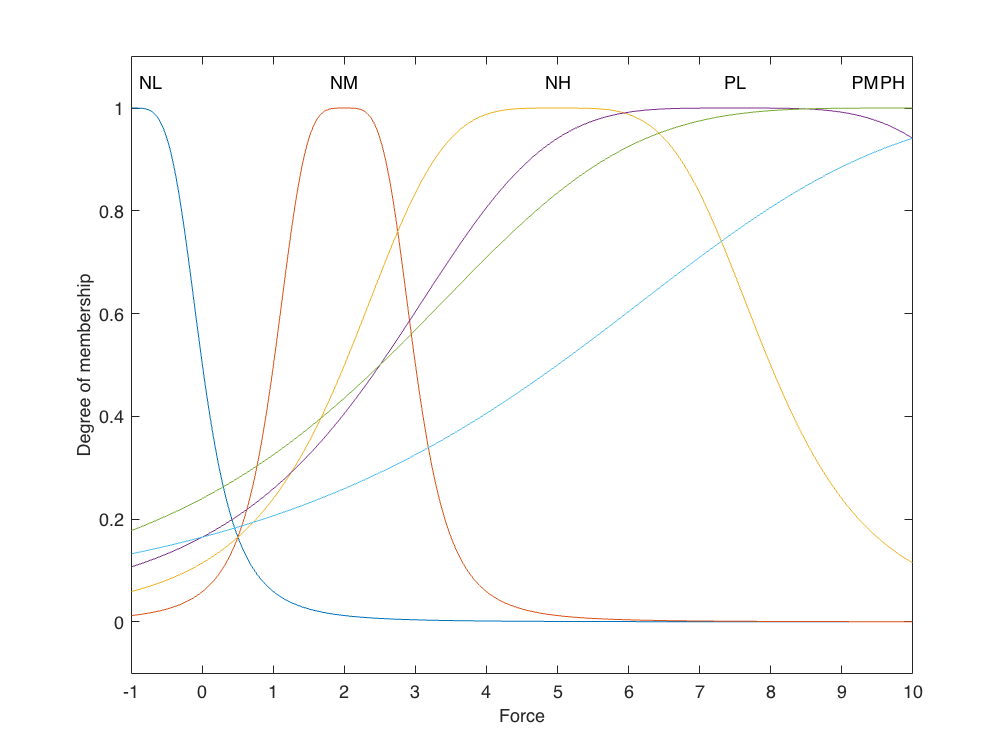

%Outputs

%Basic inference application for control just pressure

cpFIS.Outputs(1).Name = 'Force'; %Salida para controlar presion
cpFIS.Outputs(1).Range = [-1,10]; %Rango de la salida del control
%cpFIS.Outputs(1).Range = [0,10]; %Rango de la salida del control

cpFIS.Outputs(1).MembershipFunctions(1).Name = 'NL'; %Negative Low alternative
cpFIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
cpFIS.Outputs(1).MembershipFunctions(1).Parameters = [1,2,-1];

cpFIS.Outputs(1).MembershipFunctions(2).Name = 'NM'; %Negative Medium alternative
cpFIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; %Generalized bell-shaped membership function
cpFIS.Outputs(1).MembershipFunctions(2).Parameters = [1,2,2];

cpFIS.Outputs(1).MembershipFunctions(3).Name = 'NH'; %Negative High alternative
cpFIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf'; %Generalized bell-shaped membership function
cpFIS.Outputs(1).MembershipFunctions(3).Parameters = [3,2,5];
%cpFIS.Outputs(1).MembershipFunctions(1).Parameters = [5,2,-0.42];

cpFIS.Outputs(1).MembershipFunctions(4).Name = 'PL'; %Positive Low alternative
cpFIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';
cpFIS.Outputs(1).MembershipFunctions(4).Parameters = [5,2,7.5];

cpFIS.Outputs(1).MembershipFunctions(5).Name = 'PM'; %Positive Medium alternative
cpFIS.Outputs(1).MembershipFunctions(5).Type = 'gbellmf';
cpFIS.Outputs(1).MembershipFunctions(5).Parameters = [7.5,2,10];
%cpFIS.Outputs(1).MembershipFunctions(2).Parameters = [10,2,40];

cpFIS.Outputs(1).MembershipFunctions(6).Name = 'PH'; %Positive High alternative
cpFIS.Outputs(1).MembershipFunctions(6).Type = 'gbellmf';
cpFIS.Outputs(1).MembershipFunctions(6).Parameters = [10,2,15];



% cpFIS.Outputs(1).MembershipFunctions(3).Name = 'NL'; %Just a negative large alternative
% cpFIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';
% cpFIS.Outputs(1).MembershipFunctions(3).Parameters = [5,2,-10];
% cpFIS.Outputs(1).MembershipFunctions(4).Name = 'PL'; %Positive largealternative
% cpFIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';
% cpFIS.Outputs(1).MembershipFunctions(4).Parameters = [5,2,20];


plotmf(cpFIS, 'output', 1, 1000);

%Cute basic rules
% 
% rules = ["If Pref is Negative and Pobs is Negative then Force is NL";...
%     "If Pref is Positive and Pobs is Negative then Force is NM";...
%     "If Pref is Positive and Pobs is Positive then Force is PL";...
%     "If Pref is Negative and Pobs is Positive then Force is PM"];
% 
% rules = ["If Pref is Negative then Force is NM";...
%     "If Pref is Positive then Force is PM";...
%     "If Pobs is Positive then Force is PL";...
%     "If Pobs is Negative then Force is NL"];

rules = ["If Pref is Negative then Force is NM";...
    "If Pref is Positive then Force is PM"];

cpFIS = addRule(cpFIS, rules);

